# Демодуляция ЧМ-сигналов

# Phase Locked Loop Detector

**Для запуска скриптов необходимо корневую папку репозитория сделать рабочей папкой Matlab!**

### 1. Phase Locked Loop (PLL) Detector

Для качественного приема АМ-сигналов когерентным способом необходимо точное совпадение частоты и фазы несущей и генератора в приемнике. Чтобы этого добиться, нужно использовать систему фазовой автоподстройки частоты (phase-locked loop - PLL). В этом случае схема приемного устройства будет иметь вид:

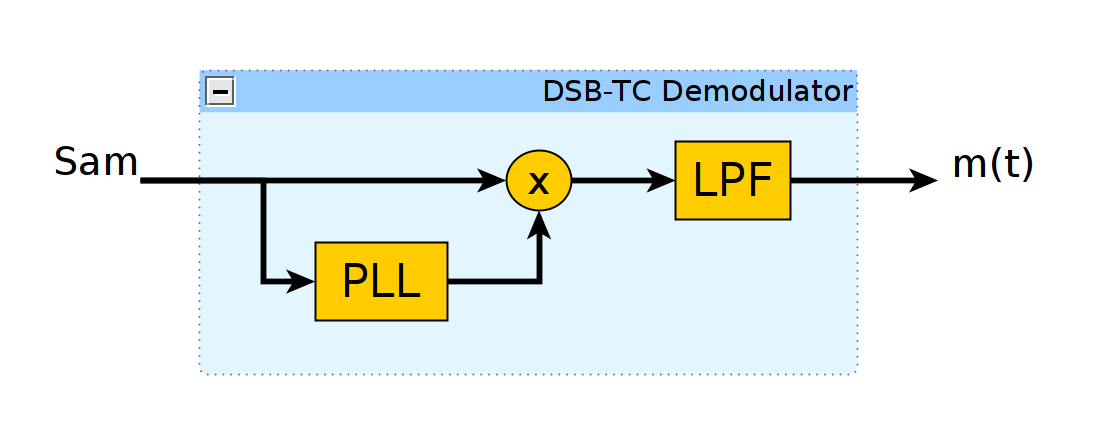

Классическая PLL состоит из трех основных блоков: фазового детектора (phase detector - PD), петлевого фильтра (loop filter - LF) и генератора, управляемого напряжением (numericaly controled oscillator - NCO). Фазовый детектор вычисляет разность фаз между несущей и NCO. Схема PLL представлена ниже:

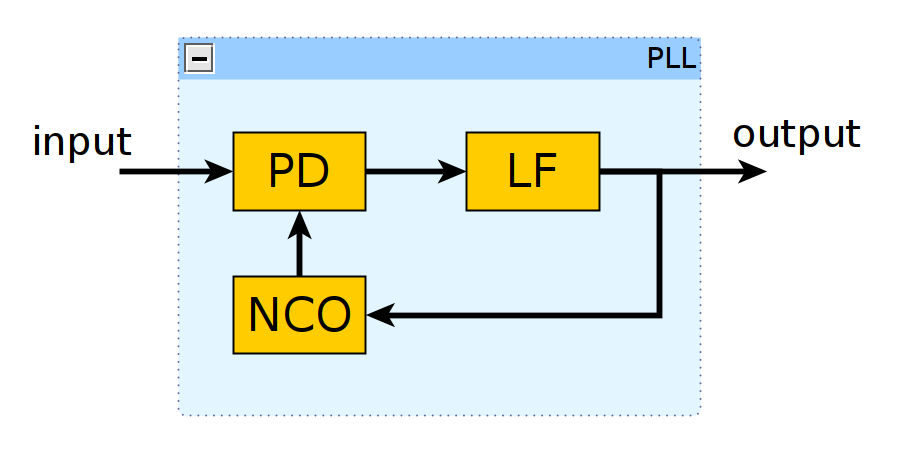

Фазовый детектор можно реализовать с помощью обычного умножителя. Будем считать, что несущую можно представить в виде:

$u_c =A\cdot \sin \left(\omega_с t+\phi_0 \right)=A\cdot \sin \left(\Phi_с \left(t\right)\right)$.

Также пусть мгновенная фаза несущей в момент времени $t_0$ равна $\Phi_с \left(t_0 \right)$ рад., а фаза NCO - $\Phi_{\textrm{NCO}} \left(t_0 \right)=\Phi_с \left(t_0 \right)-\Delta$рад. Тогда получаем:

 $A\cdot \sin \left(\Phi_с \left(t_0 \right)\right)\cdot \cos \left(\Phi_{\textrm{NCO}} \left(t_0 \right)\right)=A\cdot \sin \left(\Phi_с \left(t_0 \right)\right)\cdot \cos \left(\Phi_с \left(t_0 \right)-\Delta \right)=A\cdot 0\ldotp 5\cdot \sin \left(\Delta \right)+A\cdot 0\ldotp 5\cdot \sin \left(2\Phi_c \left(t_0 \right)-\Delta \right)$.

Слагаемое с удвоенной частотой можно убрать с помощью низкочастотного фильтра. Если этого не сделать, то оно в любом случае в дальнейшем будет удалено с помощью петлевого фильтра. Поэтому данным слагаемым можно пренебречь. То есть, отклик фазового детектора можно считать равным $A\cdot 0\ldotp 5\cdot \sin \left(\Delta \right)$. В случае, когда PLL находится в режиме синхронизации, расстройка по фазе будет близка к нулю, а значит $\sin \left(\Delta \right)\simeq \Delta \ldotp$ Таким образом, сигнал на выходе детектора будет приближенно равен $A\cdot 0\ldotp 5\cdot \Delta$. Величину $k_d =A\cdot 0\ldotp 5$ называют коэффициентом усиления детектора. Обратите внимание, что она зависит от амплитуды несущей.

Сигнал с выхода фазового детектора передается на вход петлевого фильтра, который удаляет шумы, присутствующий в сигнале, а также задает динамические характеристики PLL. Обычно фильтр реализуется в виде пропорциональной и интегрирующей ветвей, коэффициенты усиления которых равны $k_p$ и $k_i$ соответственно. Схема фильтра представлена ниже:

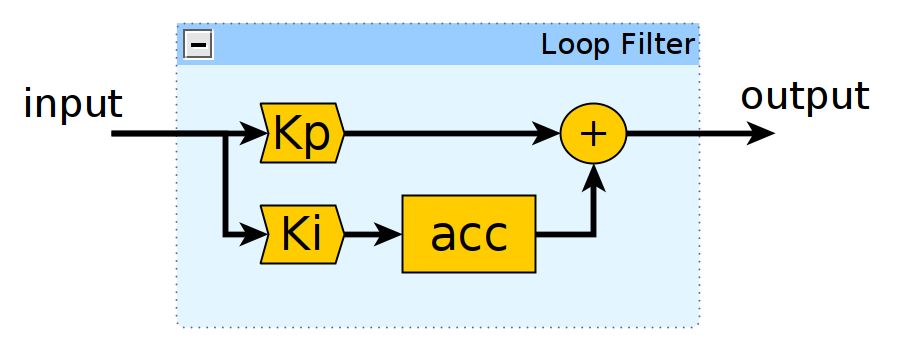

Эти коэффициенты рассчитываются на основе других характеристик PLL, а именно коэффициента демпфирования и шумовой полосы. Коэффициент демпфирования определяет степень осциляций при вхождении PLL в режим синхронизации. Шумовая полоса характеризует, как сильно будет ослаблятся шум на выходе PLL. Чем меньше полоса - тем меньше шума. Однако, уменьшение шумовой полосы приводит к существенному увеличению времени вхождения в режим синхронизации и уменьшает полосу захвата PLL. Формулы для расчета коэффициентов фильтра представлены ниже:

$k_p =\frac{4\cdot \zeta \cdot B_n }{k_d \cdot \left(\zeta +\frac{1}{4\cdot \zeta }\right)},$    $k_i =\frac{4\cdot {B_n }^2 }{k_d \cdot {\left(\zeta +\frac{1}{4\cdot \zeta }\right)}^2 }$,

 где $\zeta$ - коэффициент демпфирования, $B_n$ = $B\cdot f_s$ - нормированная шумовая полоса, $B$- шумовая полоса в герцах, $f_s$ - частота дискретизации в герцах.

Сигнал с выхода петлевого фильтра изменяется частоту управляемого генератор и тем самым подстраивает его фазу для уменьшения ошибки $\Delta$. Значание фазы NCO в аналитическом виде можно записать так:

 
$$\Phi_{\textrm{NCO}} \left(t\right)=\int_{-\infty }^t \left(\omega_0 +u_f \left(\tau \right)\right)d\tau ,$$


где $\omega_0$ - частота NCO при отсутствии входнго воздействия, $u_f \left(t\right)$ - сигнал на выходе петлевого фильтра. Таким образом, управляемый генератор по сути представляет из себя интегратор.

Так как в случаем DSB-TC модуляции несущая в сигнале присутствует в явном виде, для ее восстановления можно принятый сигнал непосредственно подавать на вход PLL. 

### 2. Демодуляция аудиосообщения

Рассмотрим демодуляцию аудиосообщения с помощью скрипта, реализующего Zero-Crossing Detector.

В файлах Audio_FM_ModIdx_*.wav записаны частотно-модулированные сигналы с различными индексами модуляции. Частота несущей $f_s$ равна 100 kHz, а частота дискретизации $f_s$ = $441$ kHz. Считаем, что прием выполняется квадратурным способ, то есть сигнал имеет вид:


$$s\left(t\right)=A_с \cdot \exp^{j\cdot \left(2\pi f_с t+2\pi K_f \cdot \int_{-\infty }^t m\left(\tau \right)\cdot d\tau \right)} \ldotp$$


Выделяя из комплексного сигнала только действительную часть, получим:


$$\textrm{real}\left\lbrace s\left(t\right)\right\rbrace =A_с \cdot \cos \left(2\pi f_с t+2\pi K_f \cdot \int_{-\infty }^t m\left(\tau \right)\cdot d\tau \right)\ldotp$$


Далее, этот сигнал подается на детектор перехода через нулевое значение. Детектор реализован с помощью сравнения знаков текущего и предыдущего отсчетов сигнала. Сравнение знаков можно реализовать через вычисление знака произведения двух последовательных отсчетов. Если знак произведения меньше нуля, то текущий и предыдущий отсчеты имеют разные знаки, и был переход через нулевое значение.

Сигнал с выхода детектора перехода через нулевое значение подается на дециматор. В состав дециматора входит фильтр нижних частот, полоса пропускания которого равна полосе информационного сообщения. Таким образом, одновременно выполняется фильтрация и децимация сигнала. После удаления постоянной составляющей получаем восстановленное аудиосообщение.

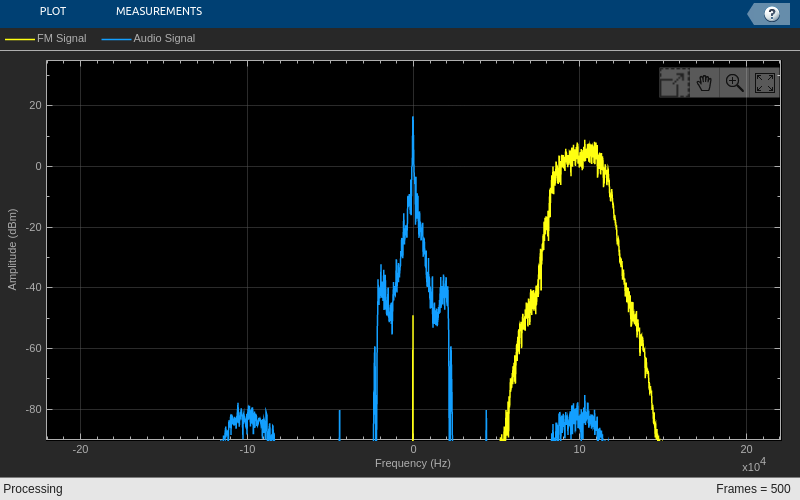

clc; clear; close all;
addpath('matlab/demodulation');

SignalFrameSize = 10000;          % количество отсчетов чм-сигнала, получаемых за один раз
FramesNumber = 500;               % число обрабатываемых пачек данных
RateRatio = 10;                   % коэффициент увеличения частоты дискретизации
AudioAmp = 1;                     % коэффициент усиления аудиосигнала
NcoAmp = 1 / 20e3;                % коэффициент усиления сигнала с выхода NCO
PllBandwidth3dB = 40e3;           % полоса пропускания PLL по уровню 3 dB
DampingFactor = 0.7;              % декремент затухания PLL
ModIndex = '1';    % индекс модуляции

% имя считываемого файла
SignalFileName = sprintf('wav/Audio_FM_ModIdx_%s.wav', ModIndex);

% объект для считываения отсчетов аудиофайла
AudioReader = dsp.AudioFileReader(...
    SignalFileName, ...
    'SamplesPerFrame',SignalFrameSize...
    );

% дополнительные расчеты
SignalFs = AudioReader.SampleRate;              % получаем частоту дискретизации модулированного сигнала
AudioFs = SignalFs / RateRatio;                 % частота дискретизации аудиосообщения

% расчет параметров PLL
ResonanceFrequency = PllBandwidth3dB / sqrt(1 + 2*DampingFactor.^2 + sqrt((2*DampingFactor.^2 + 1).^2 + 1));
NoiseBandwidth = ResonanceFrequency * (2*pi) * (DampingFactor + 0.25/DampingFactor) / 2;

PLL = ComplexPLL( ...
    'SampleFrequency', SignalFs, ...
    'NoiseBandwidth', NoiseBandwidth, ...
    'Dampingfactor', DampingFactor, ...
    'CentralFrequency', 100e3 ...
    );

% дециматор 
DownSampler = dsp.SampleRateConverter(...
    'Bandwidth', 30e3, ...
    'InputSampleRate', SignalFs, ...
    'OutputSampleRate', AudioFs ...
    );

% объект для вычисления спектра
SpecEstimator = dsp.SpectrumEstimator(...
    'PowerUnits','dBm',...
    'FrequencyRange','centered',...
    'SampleRate',SignalFs);

% объект для отрисовки графиков
Plotter = dsp.ArrayPlot(...
    'PlotType','Line', ...
    'XOffset', -SignalFs/2, ...
    'YLimits', [-90, 35], ...
    'XLabel', 'Frequency (Hz)', ...
    'YLabel', 'Amplitude (dBm)', ...
    'ChannelNames', {'FM Signal', 'Audio Signal'}, ...
    'SampleIncrement', SignalFs/SignalFrameSize ...
    );

Message = [];

% запуск симуляции
for i = 1:FramesNumber
    % считывание отсчетов ЧМ-сигнала и выделение синфазного канала
    FmSignal = AudioReader();
    FmSignal = FmSignal(:,1) + 1j*FmSignal(:,2);
    
    % удаление постоянной составляющей
    FmSignal = FmSignal - mean(FmSignal);
 
    % частотная демодуляция с помощью PLL
    [~, NcoOutput] = PLL(FmSignal);

    % нормирование выхода NCO
    NcoOutput = NcoOutput .* NcoAmp;

    % понижение частоты дискретизации
    AudioSignal = DownSampler(NcoOutput);
    
    % убираем постоянную составляющую
    AudioSignal = AudioSignal - mean(AudioSignal);
    
    % формирование итогового сллбщения
    Message = [Message; AudioAmp * AudioSignal];

    % вычисление спектров
    SpectrumData = SpecEstimator([FmSignal NcoOutput]);

    % вывод результатов на график
    Plotter(SpectrumData)

    % задержка в 0.1 секунды для лучшей визуализации
    pause(0.01)
end

На спектрограмме желтым показан спектр частотно-модулированного сигнала, а синим - спектр на выходе детектора перехода через нулевое значение. Так как сигнал на выходе детектора импульсный, его спектр содержит сильные высокочастотные компаненты. 

% проигрывание полученного сообщения
sound(Message, AudioFs);

На слух можно понять, что аудиосообщение восстанавливается, однако сопровождается шумами. Одной из причин является заворот высокочастотных компонент относительно частоты Найквиста. Они попадают в полосу сообщения, и их уже невозможно отфильтровать. Причем, чем меньше индекс модуляции, тем сильнее шумы. Таким образом, Zero-Crossing Detector хуже работает при сигналах с низким индексом модуляции. 

Также отметим, что в данном демодуляторе подсчитывается число переходов через нулевой уровень. Чем больше таких переходов будет на интервале подсчета, тем точнее будет оценка мгновенной частоты. Количество переходов напрямую зависит от частоты несущей $f_с$. То есть, при использовании Zero-Crossing Detector лучше, чтобы частота несущей была выше.

### 3. Демодуляция FM-радио в Matlab

Ниже представлен скрипт, позволяющий прослушивать FM-радио с помощью RTL-SDR. Настройка на нужную радиостанцию выполняется с помощью переменной Fc, которая задает частоту несущей. Входной сигнал проходит через фильтр нижных частот для выделения нужной радиостанции. Далее сигнал с помощью умножения на комплексную экспоненту сдвигается на 200 kHz. Как упоминалось ранее, чтобы увеличить число переходов через нулевое значение, желательно, чтобы частота несущей была как можно выше. Частота сдвига в 200 kHz - это приемлемое решение при заданной частоте дискретизации. У сдвинутого по частоте сигнала выделяется действительная часть, и она поступает на Zero-Crossing Detector. В заключение сигнал децимируется, у него удаляется постоянная составляющая и он подается на звуковую карту. 

clc; clear; close all;
addpath('matlab/demodulation');

Fc = 106.2e6;                % частота несущей в Hz
SignalFs = 1.2e6;            % частота дискретизации RTL-SDR
AudioFs = 48e3;              % частота дискретизации демодулированного аудиосигнала
SignalFrameSize = 512*25;    % количество отсчетов чм-сигнала, получаемых за один раз
AudioAmp = 0.05;             % коэффициент усиления аудиосигнала
NcoAmp = 1 / 20e3;           % коэффициент усиления сигнала с выхода NCO
PllBandwidth3dB = 40e3;      % полоса пропускания PLL по уровню 3 dB
DampingFactor = 0.7;         % декремент затухания PLL

SDRRTL = comm.SDRRTLReceiver(...
    'RadioAddress', '0',...
    'CenterFrequency', Fc,...
    'EnableTunerAGC', true,...
    'SampleRate', SignalFs, ...
    'SamplesPerFrame', SignalFrameSize,...
    'OutputDataType', 'double' ...
);

% расчет коэффициентов и создание фильтра нижних частот
Fpass = 110e3;
Fstop = 160e3;
H = Audio_Lowpass_FIR_Coeff(SignalFs, Fpass, Fstop);
LowpassFIR = dsp.FIRFilter(H.Numerator);

% расчет параметров PLL
ResonanceFrequency = PllBandwidth3dB / sqrt(1 + 2*DampingFactor.^2 + sqrt((2*DampingFactor.^2 + 1).^2 + 1));
NoiseBandwidth = ResonanceFrequency * (2*pi) * (DampingFactor + 0.25/DampingFactor) / 2;

PLL = ComplexPLL( ...
    'SampleFrequency', SignalFs, ...
    'NoiseBandwidth', NoiseBandwidth, ...
    'Dampingfactor', DampingFactor, ...
    'CentralFrequency', 0 ...
    );

% дециматор 
DownSampler = dsp.SampleRateConverter(...
    'Bandwidth', 30e3, ...
    'StopbandAttenuation', 80, ...
    'InputSampleRate', SignalFs, ...
    'OutputSampleRate', AudioFs ...
    );

% объект для вычисления спектра
SpecEstimator = dsp.SpectrumEstimator(...
    'PowerUnits','dBm',...
    'FrequencyRange','centered',...
    'SampleRate',SignalFs);

% объект для отрисовки графиков
Plotter = dsp.ArrayPlot(...
    'PlotType','Line', ...
    'XOffset', -SignalFs/2, ...
    'YLimits', [-90, 35], ...
    'XLabel', 'Frequency (Hz)', ...
    'YLabel', 'Amplitude (dBm)', ...
    'ChannelNames', {'FM Signal'}, ...
    'SampleIncrement', SignalFs/SignalFrameSize ...
    );

% воспроизведение аудио сигнала
AudioSink = audioDeviceWriter(AudioFs);

% запуск симуляции
while(true)
    % получение отсчетов сигнала
    FmSignalData = SDRRTL();
    
    % вычисление спектров и вывод результатов на график
    SpectrumData = SpecEstimator(FmSignalData);
    Plotter(SpectrumData);
    
    % удаление постоянной составляющей
    FmSignalData = FmSignalData - mean(FmSignalData);
    
    % фильтрация
    FilteredData = LowpassFIR(FmSignalData);
    
     % частотная демодуляция с помощью PLL
    [~, NcoOutput] = PLL(FilteredData);

    % нормирование выхода NCO
    NcoOutput = NcoOutput .* NcoAmp;
    
    % уменьшение частоты дискретизации
    AudioData = DownSampler(NcoOutput);
   
    % удаляем постоянную составляющую
    AudioData = AudioData - mean(AudioData);
    
    % проигрывание данных
    AudioSink(AudioData * AudioAmp);
  
end

### 4. Демодуляция FM-радио в Simulink

В файле FM_SDR_Receiver_PLL_Detectoer.slx представлена Simulink-модель, позволяющая прослушивать FM-радио с помощью RTL-SDR. Все преобразования сигнала совпадают с теми, что ранее были описаны в Matlab скрипте.

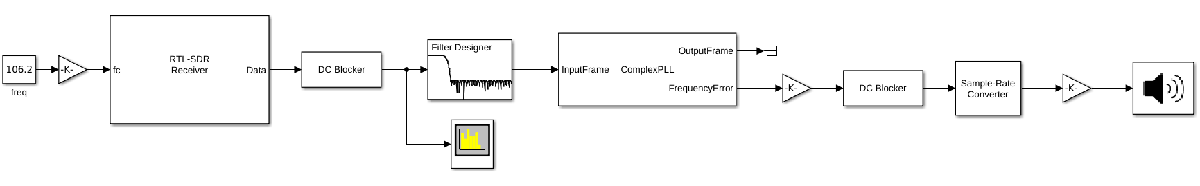

### Литература:

- B. P. Lathi Modern Digital and Analog Communication Systems

- R. Stewart, K. Barlee, D. Atkinson, L. Crockett Software Defined Radio using MATLAB® & Simulink and the RTL-SDR